# lora sim script

## lora parameters

%clear;
SF=12; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
numSym=round(50000/SF);
%numSym=20;

randomData=false;
enableFilters=false;
%channel
perfectChannel=false;%no  awgn
maxDopplerShift=0;%20e3;%0.45*Fs/(2^SF);%shift has to be less than 0.5*Fs/(2^SF) to have no impact
flatDoppler=true;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=5; %signal to noise ratio in dB
%loops
nLoops=20;
loopSNR=true;
SNRstepsize=2;
loopDoppler=false;
dopplerRate=100;
dopplerStepsize=dopplerRate/Fs;%dopplerrate*sampletime

plotSpectrogram=true;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    symbol=0;%generate symbols with certain value
    messageBits=transpose(repmat(dec2bin(symbol,SF)-'0',1,numSym));% -'0' to convert binary string to vector
end
%generate lora signal
[loraSignal,decimalSymbols]=generateLoraSignal(messageBits,SF,numSym);
decimalSymbols

decimalSymbols =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


if plotSpectrogram
    %spectroram of first 5 symbols
    figure
    windowLength=round((SPS)/10);
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
    title('Spectrogram with freq and time')
    % figure
    % spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
    % title('Spectrogram with freq index and samples')
end


if enableFilters
    rolloff = 0.25;  % Roll-off factor for the RRC filter
    span = 6;  % Filter span in symbols
    L=8;
    rrcFilter = rcosdesign(rolloff, span, L);
    %impz(rrcFilter)
    txSignal= conv(loraSignal, rrcFilter, 'same');
else
    txSignal = loraSignal;
end

## channel & rx

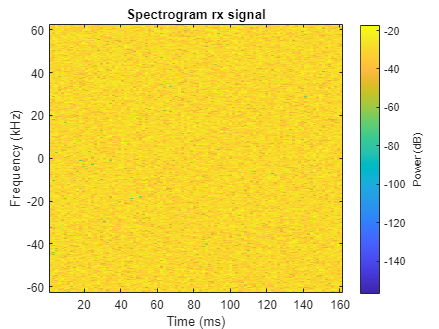

  Columns 1 through 2,730

        2309        3966        2035        1076         200        1171        2064        2896         739        3164        2702        1108        1937           0        4022        1045        1319        1963        3843        1802         844         950        2620        3229        2426        2163        1437        2123         271        3968         239        1072        2150        2736        2571         331           0        3852        2232        3286         783        1072        2472        1087         566        1500         488        1603        1785        2596         611        3443        2084        1736        1375         353        3090         229        1286        2342         866        2492         264        3899        2008        1600        3906         109        1055        1295        1386         218         172        1854        2312        1025        2956        3091        3729         607          88 

%channel
for counter=1:nLoops


    symbolDuration=(2^SF)/Fs;

    t=(symbolDuration/2^SF:symbolDuration/2^SF:symbolDuration*numSym);
    
    if flatDoppler
        freqShift=maxDopplerShift;
        dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    else%apply dopper rate
        freqShift=zeros(1,length(t));
        
        for i=1:length(t)
            freqShift(i)=maxDopplerShift+dopplerRate*t(i);
        end
        %freqShift=linspace(dopplerShift,-dopplerShift,length(t));
        dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    end
    
    if perfectChannel% use maxDopplerShift = 0 for truly perfect channel
        rxSignal = txSignal.* (dopplerEffect);
    
    else
        if loopSNR
            rxSignal=(awgn(txSignal,maxSNR-(counter-1)*SNRstepsize,'measured'));
        else
            rxSignal=(awgn(txSignal,maxSNR,'measured'));
        end
        %snr
    end

    if (plotSpectrogram && counter==nLoops)
        %spectroram of first 5 symbols

        figure
        windowLength=round((SPS)/10);
        spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
        title('Spectrogram rx signal')
        % figure
        % spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
        % title('Spectrogram with freq index and samples')
    end

    %rx
    if enableFilters
        matchedFilter = rcosdesign(rolloff, span, L);
        rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
    else
        rxSignalFiltered = rxSignal;
    end
    [decodedBits,decodedSymbols]=demodulateLoraSignal(rxSignalFiltered,SF,numSym);
    if counter==nLoops
        disp(decodedSymbols)
    end
    errors(counter)=sum(messageBits~=decodedBits);
end

## doppler estimation

symbolOffset=decodedSymbols-decimalSymbols;
preambleLength=20;
estDopplerOffset=(symbolOffset/2^SF)*Fs

estDopplerOffset = 1.0e+05 *

    0.7047    1.2103    0.6210    0.3284    0.0610    0.3574    0.6299    0.8838    0.2255    0.9656    0.8246    0.3381    0.5911         0    1.2274    0.3189    0.4025    0.5991    1.1728    0.5499    0.2576    0.2899    0.7996    0.9854    0.7404    0.6601    0.4385    0.6479    0.0827    1.2109    0.0729    0.3271    0.6561    0.8350    0.7846    0.1010         0    1.1755    0.6812    1.0028    0.2390    0.3271    0.7544    0.3317    0.1727    0.4578    0.1489    0.4892    0.5447    0.7922


symbolDuration=(2^SF)/Fs;
indices = round(linspace(1, length(freqShift), preambleLength));

freqShiftValues = freqShift(indices)

freqShiftValues =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



estDopplerRate=0.5*(estDopplerOffset(preambleLength)-estDopplerOffset(1))/(preambleLength*symbolDuration)

estDopplerRate = -1.1805e+04

symbolTimes=linspace(symbolDuration,preambleLength*symbolDuration,preambleLength)

symbolTimes =     0.0328    0.0655    0.0983    0.1311    0.1638    0.1966    0.2294    0.2621    0.2949    0.3277    0.3604    0.3932    0.4260    0.4588    0.4915    0.5243    0.5571    0.5898    0.6226    0.6554



correctedSymbols=round(decodedSymbols(1:preambleLength)-((estDopplerOffset(1)+estDopplerRate*symbolTimes)/Fs)*2^SF)

correctedSymbols =           13        1682        -236       -1182       -2046       -1062        -156         688       -1456         982         532       -1049        -207       -2132        1903       -1061        -775        -118        1775        -254


## other method



% Multiply the signal with its complex conjugate
% r = rxSignal .* conj(rxSignal);
% 
% angle(rxSignal)

z = rand(1, 81920) + 1i*rand(1, 81920); % Example complex vector

% Compute the conjugate of the signal
z_conj = conj(z);

% Multiply the signal with its complex conjugate
r = z .* z_conj;
% Number of samples
N = length(r);

% Indices for the 4 phases
indices = [N/4, N/2, 3*N/4, N];
phase1=angle(sum(rxSignal(1:indices(1))))

phase1 = 2.0458

phase2=angle(sum(rxSignal(indices(1):indices(2))))

phase2 = 1.4479

phase3=angle(sum(rxSignal(indices(2):indices(3))))

phase3 = -2.0074

phase4=angle(sum(rxSignal(indices(3):indices(4))))

phase4 = 1.9288


fd=((phase2+phase4)-(phase1+phase3))/(2*pi*N*(1/Fs))

fd = 0.8107

rd=((phase4-phase3)-(phase2-phase1))/(pi*(N/2)^2 *(1/Fs)^2)

rd = 13.4410

## ber

'Adaptive Parameters for LoRa-Based Networks Physical-Layer' for ber formula

lora_ber=errors/dataLength

lora_ber =          0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0085    0.0875    0.2616    0.3964    0.4639    0.4877


lora_ser=sum(transpose(decimalSymbols~=decodedSymbols))/numSym

lora_ser = 0.9726

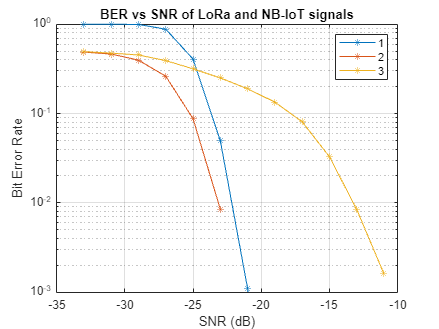

% lora_ber7=errors/dataLength
% lora_ber10=errors/dataLength
% lora_ber12=errors/dataLength

if loopSNR
    figure
    
    SNRvec=flip((maxSNR-(nLoops-1)*SNRstepsize):SNRstepsize:maxSNR);
    theoryBer12=qfunc((log(12)/log(12))/sqrt(2)*(SNRvec+10*log10((2^12)/12)));
    
    theoryBer7=-0.5+qfunc((log(7)/log(12))/sqrt(2)*(SNRvec+10*log10((2^7)/7)));
    semilogy(SNRvec',theoryBer12,'-*')
    hold on
    semilogy(SNRvec',lora_ber,'-*')
    
    % semilogy(SNRvec',theoryBer7,'-*')
    %hold on
    %semilogy(SNRvec',lora_ber7,'-*')
    
    %semilogy(SNRvec',lora_ber10,'-*')
    semilogy(SNRvec',lora_ber12,'-*')
    
    %semilogy(SNRvec',nbiot_ber,'-*')
    grid on
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    ylim([10e-4 1])
    %legend('theory 12','theory 7','SF 7','SF 9','SF 12')%adjust legend!
    legend( '1','2','3')
    title('BER vs SNR of LoRa and NB-IoT signals')
    
end


%% compare with nbiot


## doppler corection

shifting the signal with n kHz will shift the demodulated symbol with (dopplerShift/BW)*2^SF

e.g. with SF=7, symbol 0 will be demodulated as 66 when the signal is shifted with 64 kHz 

original symbol = received symbol -(dopplerShift/125kHz)*2^SF)

to estimate frequency shift: ((receivedSymbol-expectedSymbol)/2^SF)*BW